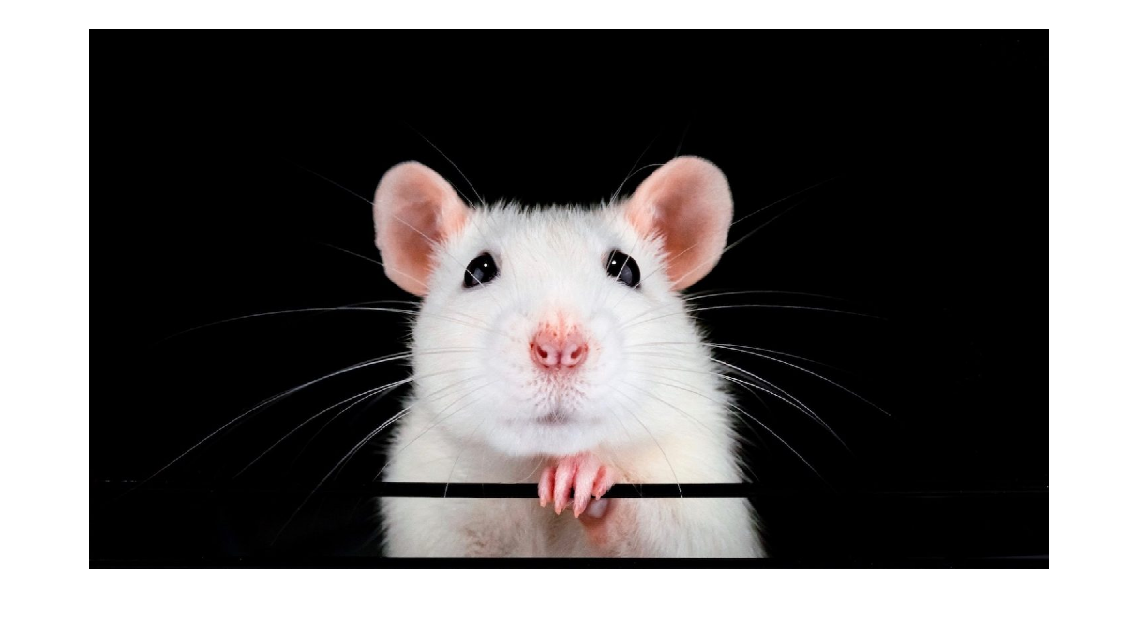

clc; clear; close all

img=imread('Test_rat_image2.jpg');
imshow(img)

I=rgb2gray(img);

%I_sobel=edge(I,'Sobel');
[I_test, threshold]=edge(I,'Canny');

Threshold (adjust slider that isolates the eyes the most)

threshold

threshold =     0.0063    0.0156


I_edge=edge(I,'Canny',46.9* threshold);



Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0]);
I_clear=imclearborder(I_erode);

I_final=labeloverlay(img,I_clear);

Final images

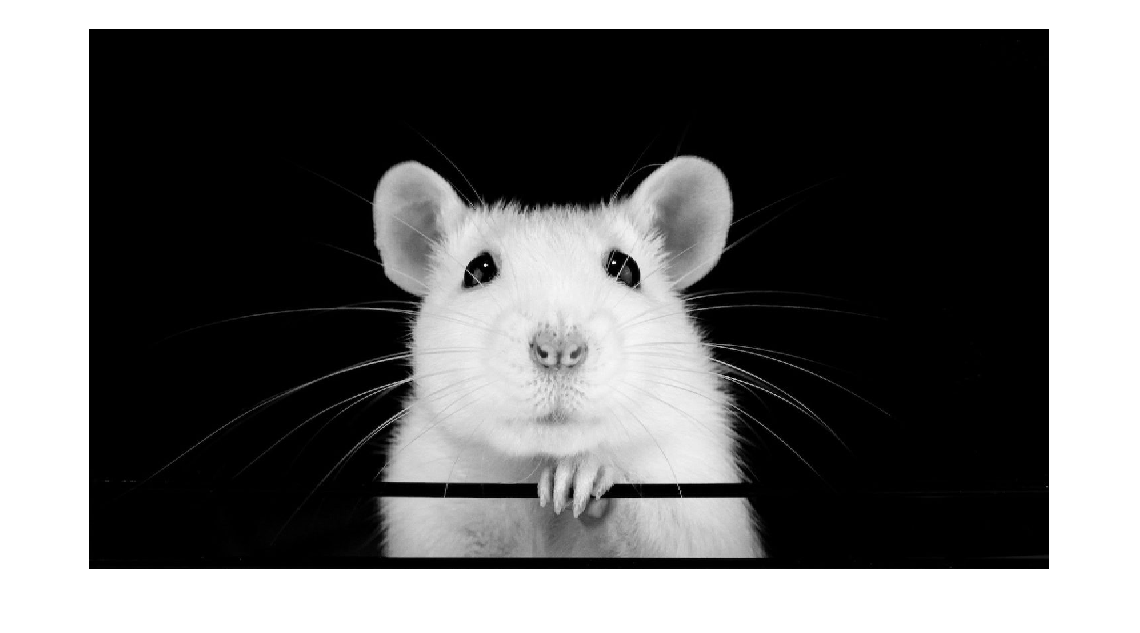

imshow(I)

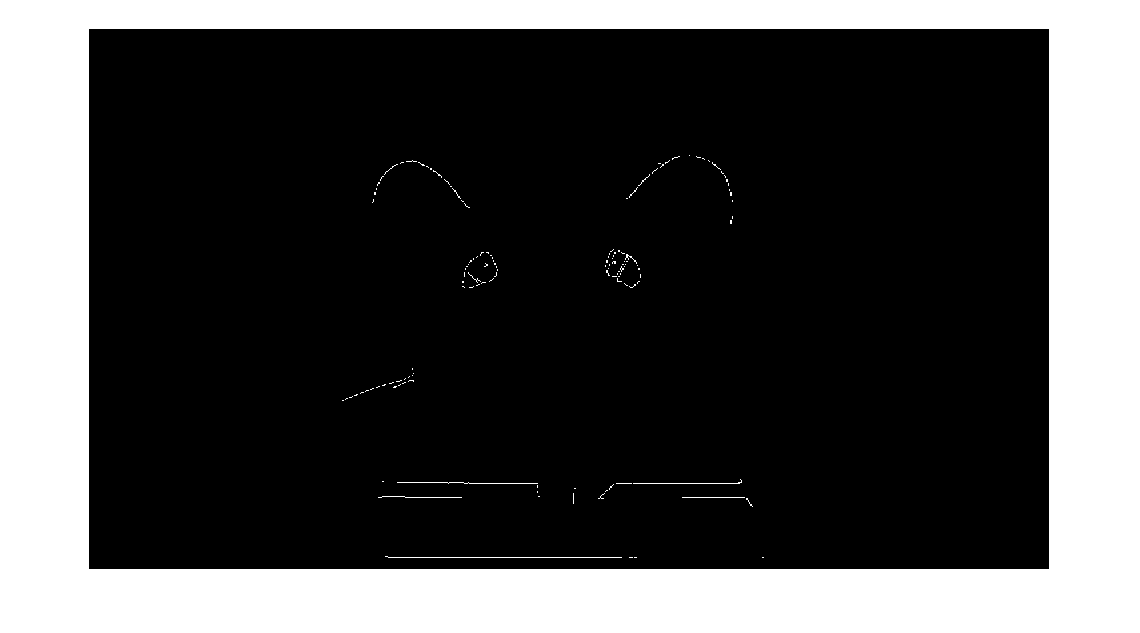

imshow(I_edge)

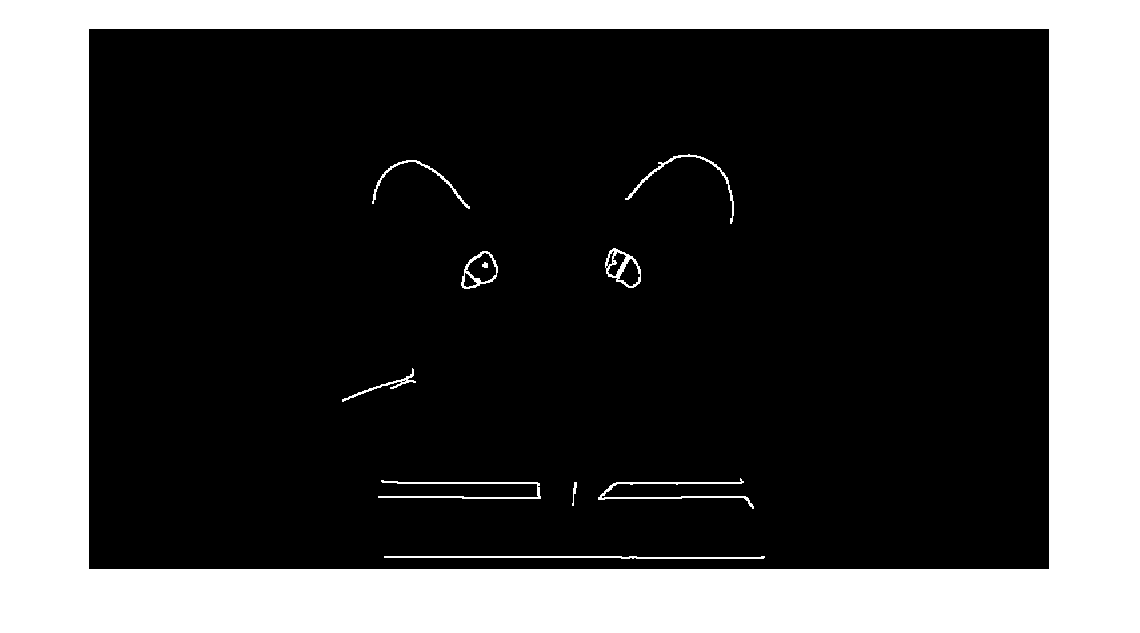


imshow(I_dilate)

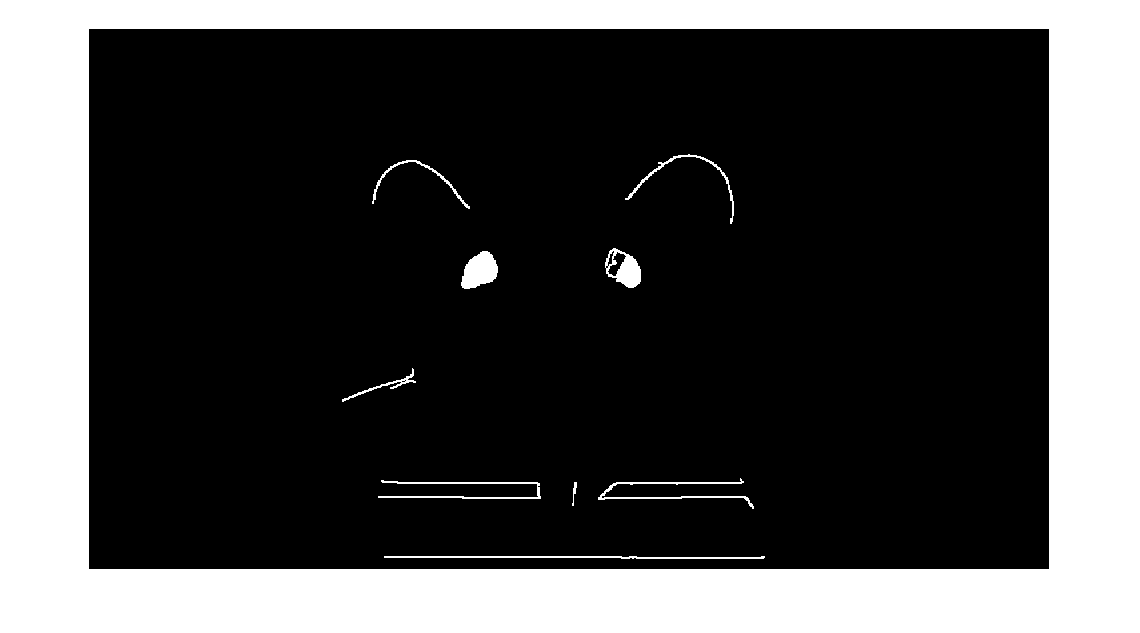

imshow(I_fill)

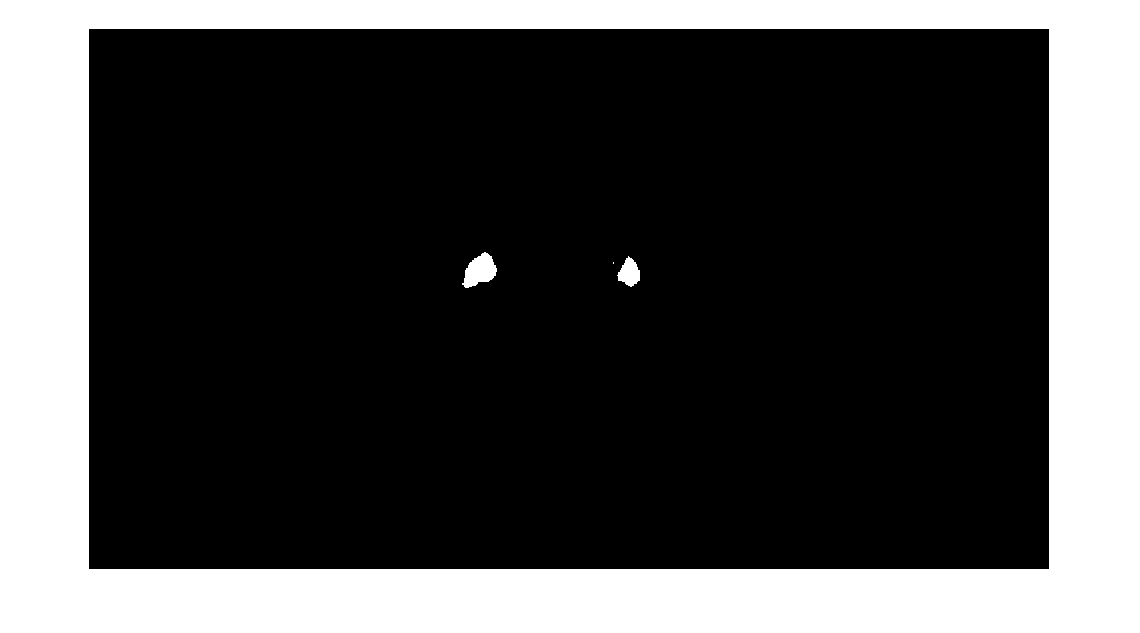

imshow(I_erode)

imshow(I_clear)

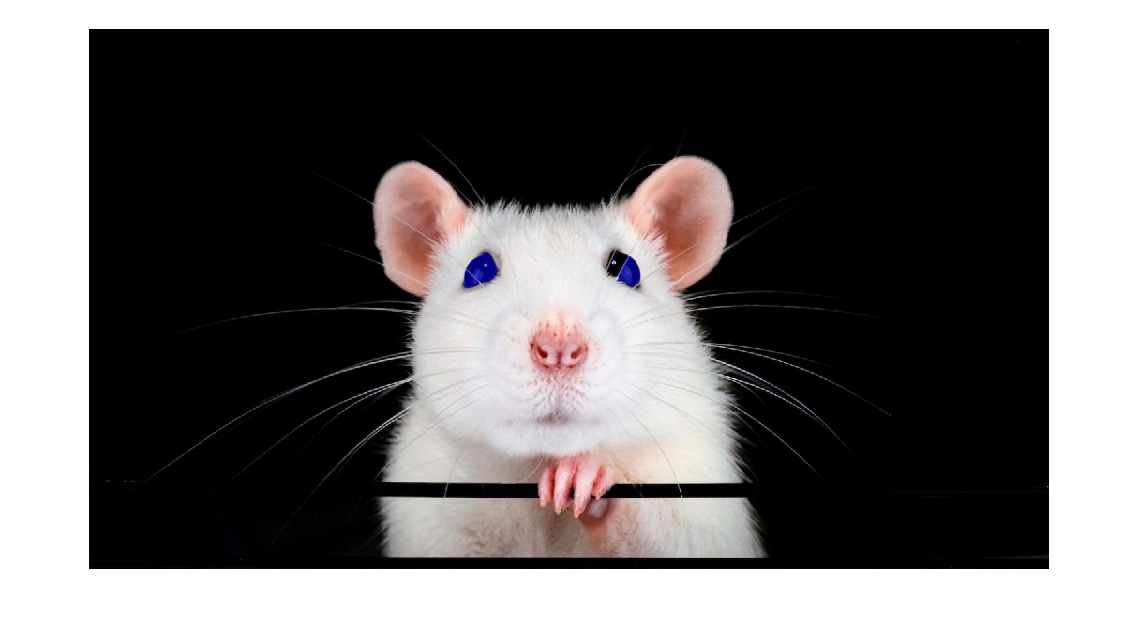


imshow(I_final)

Calculation of eye's area (biggest on image) and normalized value

region=regionprops(I_clear)

region = 4×1 struct array with fields:
    Area
    Centroid
    BoundingBox


Area=[region.Area]

Area =         1746           8         986           2


eye_Area=Area(find(Area==max(Area)))

eye_Area = 1746


% % area of entire image
% [x,y]=size(img)
% T_area=x*y
% % normalized from image size
% 
% Norm_eye_Area=eye_Area/T_area
